clear all

# Refined Wing Sizing

## Deriving the wing geometry

Create the panels that make up the wing based on input variables and proportional relationship between landing gear geometry to wing sizing (derived from A321neo)

### Input variables

taper_ratio = 0.25;
sweep_angle = 25;
wingspan = 40000; % mm
aspect_ratio = 11.7;
wing_area = (wingspan)^2 / aspect_ratio;
c_lg = 1920; % mm
fuselage_radius = 0.5 * 3940; % mm
wingtip_span = 2000; % mm 

### Initial wing sizing

Calculate the wing root and tip chord based on a simple trapezium shape, these values are not the final values for the wing but act as a baseline to refine from.

cr = ((2 * wing_area) / ((1 + taper_ratio) * wingspan)); % Root chord
ct = ((2 * wing_area) / wingspan) - cr; % Tip chord

### Determine panel vertices

### Wing kink

The wing kink location is determined by the placement of the landing gear

% y-position of kink is approximated based on landing gear chord and
% fuselage radius, all proportionally scaled relative to the A321neo design
y_kink = 1.405*((3760/1920)*c_lg + (840/1957)*fuselage_radius);

% Define straight line equation for both the trailing and leading edge of
% the wing, this is used to calculate the x-position of each panel boundary
% based on known y-positions
gamma = ct + (0.5*wingspan-fuselage_radius)*tand(sweep_angle);
m_te = (0.5*wingspan - fuselage_radius) / (gamma - cr);
c_te = fuselage_radius - m_te*cr;

m_le = (0.5*wingspan - fuselage_radius) / (gamma - ct);
c_le = fuselage_radius;

% x-position of kink for both trailing and leading edge
x_kink_te = (y_kink - c_te) / m_te;
x_kink_le = (y_kink - c_le) / m_le;

### Folding wingtip

% y-position of folding wingtip root
y_folding_tip = 0.5*wingspan - wingtip_span;

% x-position of folding wingtip root for both trailing and leading edge
x_folding_tip_te = (y_folding_tip - c_te) / m_te;
x_folding_tip_le = (y_folding_tip - c_le) / m_le;

### Create 2D matrix of panels

% Panels are represent as a 2D matrix as shown:
%
% [x1 y1 z1]
% [x2 y2 z2]
% [x3 y3 z3]
% [x4 y4 z4]
%
% The panels are "drawn" anti-clockwise, so LE is bounded between 
% [x2 y2 z2] and [x1 y1 z1], etc.

foldy_boi_panels = {
    [0 0 0; 0 fuselage_radius 0; x_kink_te fuselage_radius 0; x_kink_te 0 0],
    [0 fuselage_radius 0; x_kink_le y_kink 0; x_kink_te y_kink 0; x_kink_te fuselage_radius 0],
    [x_kink_le y_kink 0; x_folding_tip_le y_folding_tip 0; x_folding_tip_te y_folding_tip 0; x_kink_te y_kink 0],
    [x_folding_tip_le y_folding_tip 0; gamma-ct 0.5*wingspan 0; gamma 0.5*wingspan 0; x_folding_tip_te y_folding_tip 0]
};

panel_colours = ["#FFFFFF" "#FFFFFF" "#FFFFFF" "#FF0000"];

### Additional wing geometric properties

foldy_boi_rtp = 0.15; % Root thickness percentage of chord
foldy_boi_ttp = 0.1; % Tip thickness percentage of chord
foldy_boi_dihedral = 4; % Dihedral angle of the wing, deg

%foldy_boi = Wing(foldy_boi_panels, foldy_boi_rtp, foldy_boi_ttp, foldy_boi_dihedral);

%draw_wing(foldy_boi);
%view([270 90.00])

## Initial Visualisation

Graph the planform shape of the wing using individual panels defined as trapeziums bounded by 4 points

$\textrm{panel}=\left\lbrack \begin{array}{ccc}
x_1  & y_1  & z_1 \\
x_2  & y_2  & z_2 \\
x_3  & y_3  & z_3 \\
x_4  & y_4  & z_4 
\end{array}\right\rbrack$,

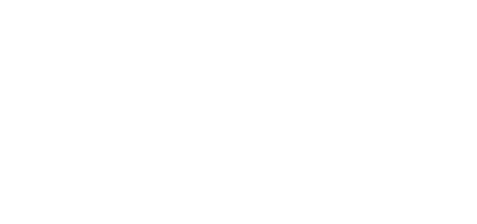

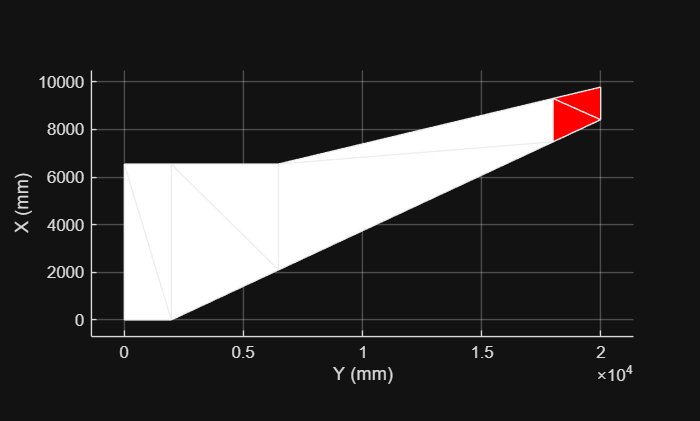

% Creating the wing instance
foldy_boi = Wing(foldy_boi_panels, panel_colours, foldy_boi_rtp, foldy_boi_ttp, foldy_boi_dihedral);
draw_wing(foldy_boi);
view([270 90.00])

## Subdividing the wing

Subdivide each panel into subpanels. This increases accuracy of calculated quantities as $\Delta y\longrightarrow 0$.

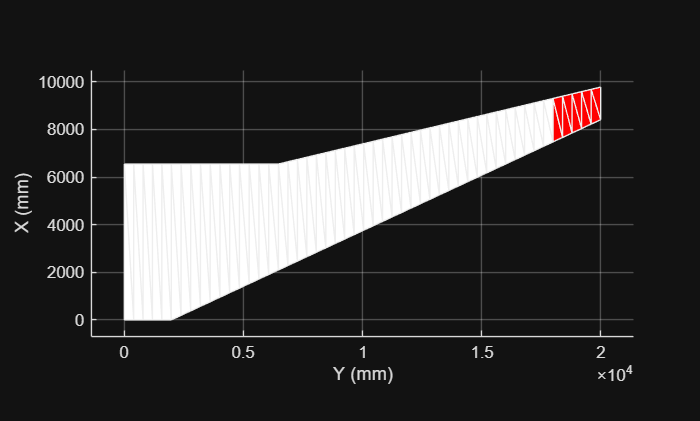

% Subdivide the wing 'n' times and draw again
foldy_boi.subdivide_wing(50);
draw_wing(foldy_boi);
view([270 90.00])

## Extruding the wing

Extrude the wing into 3D by utilising the wing's root and tip thickness percentage of the root cord.

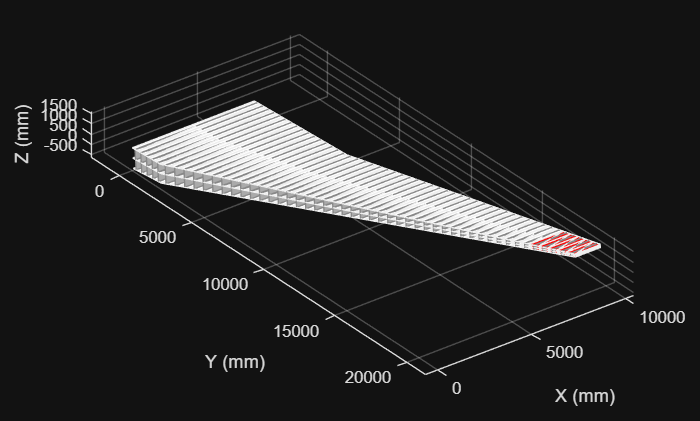

foldy_boi.extrude_wing();
draw_wing(foldy_boi);

## Adding the engine

Add the engine to the wing at some x- and y-position. Used for visualisation but also correct the shear loading across the span of the wing.

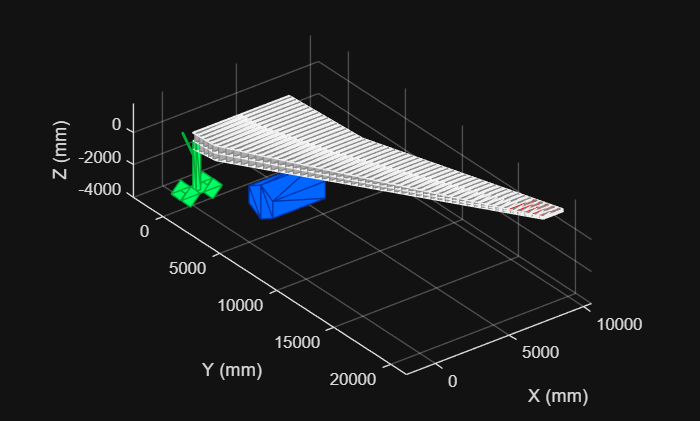

% Create a new engine of given diameter, length and mass
engine = Engine(2110, 3550, 3271.87);
landing_gear = LandingGear(3000);

% Add the engine to the wing at y-location, the engine will be placed such
% that half its length coincides with the leading edge of the wing at the
% bottom skin (requires the wing to be extruded)
foldy_boi.add_engine(engine, 6000);
foldy_boi.add_landing_gear(landing_gear);

draw_wing(foldy_boi);

## Analysing structural performance

Calculate the net beam loading, shear, bending moment, deflection angle and absolute deflection at each point along the wing. Values are calculated at the average of a panel (so more panels = better precision).

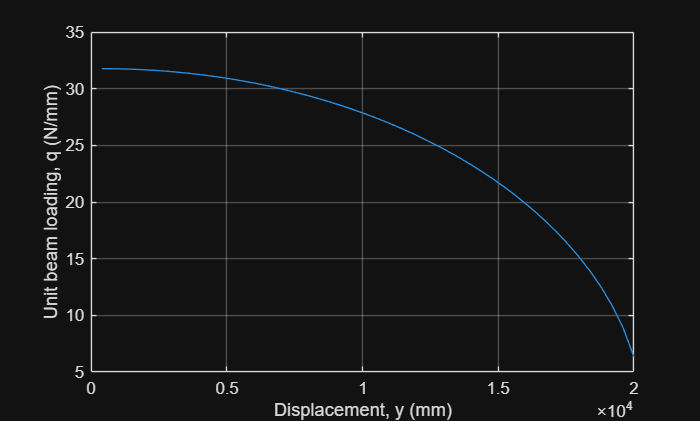

m = 101e3; % kg
g = 9.880665; % m/s/s
W = m * g; % N

engine_m = 3271.87; % kg
W_engine = engine_m * g;

E = 71000;

[q, S, M, deflection_angle, deflection] = foldy_boi.calc_structural_metrics(W, E);

y = cellfun(@(x) x(2, 2), foldy_boi.panels)';

plot(y, q)
grid on
xlabel('Displacement, y (mm)')
ylabel('Unit beam loading, q (N/mm)')

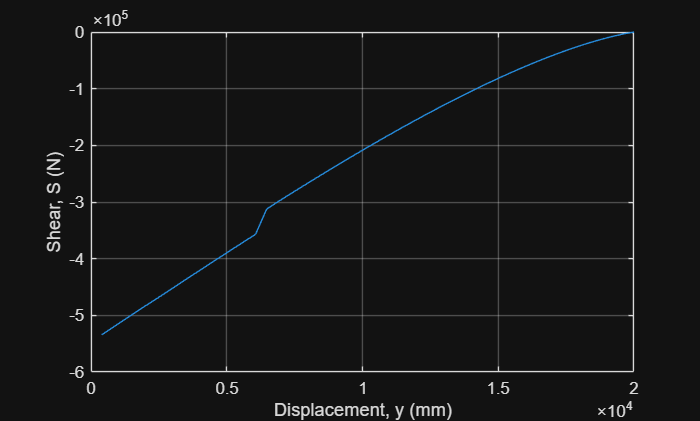


plot(y, S)
grid on
xlabel('Displacement, y (mm)')
ylabel('Shear, S (N)')

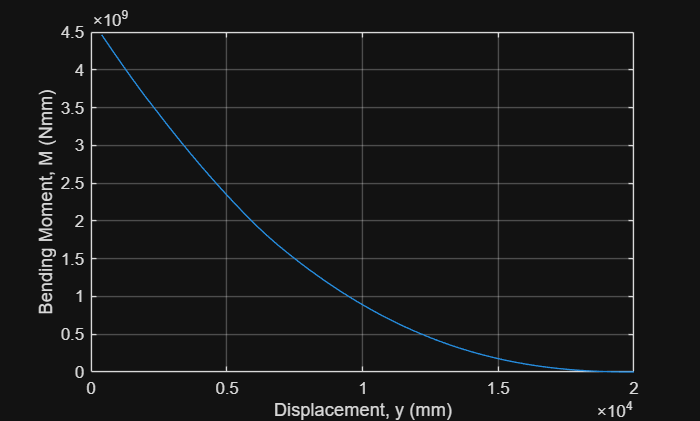


plot(y, M)
grid on
xlabel('Displacement, y (mm)')
ylabel('Bending Moment, M (Nmm)')

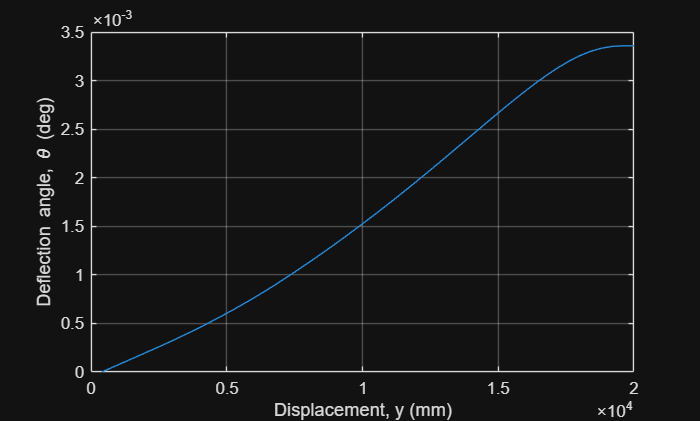


plot(y, deflection_angle)
grid on
xlabel('Displacement, y (mm)')
ylabel('Deflection angle, \theta (deg)')

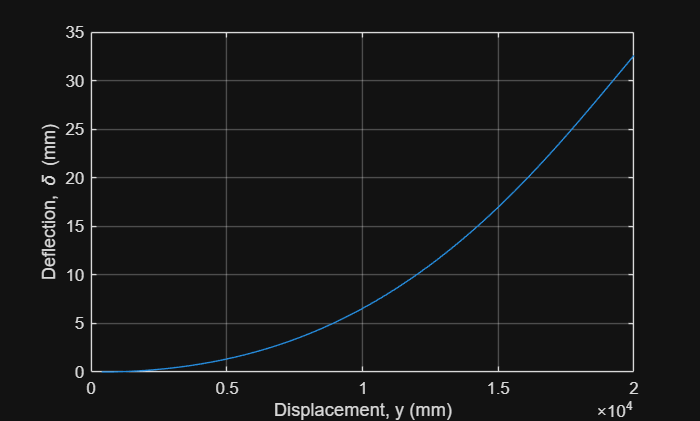


plot(y, deflection)
grid on
xlabel('Displacement, y (mm)')
ylabel('Deflection, \delta (mm)')

## Resultant forces on wing

Draw the wing again now that deflection angles have been computed

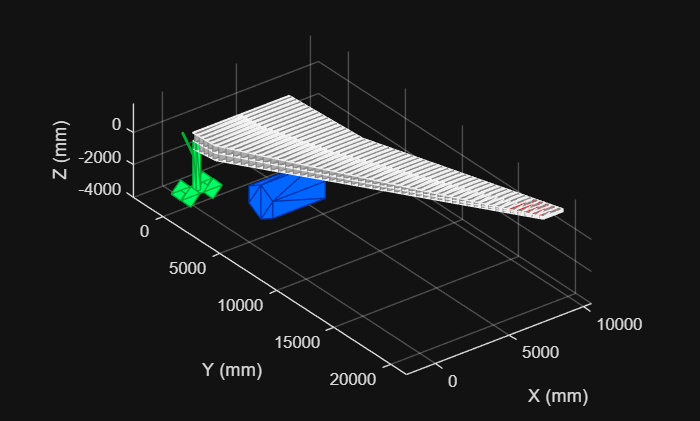

draw_wing(foldy_boi);


foldy_boi.taper_ratio

ans = 0.2089

foldy_boi.aspect_ratio

ans = 10.3960

foldy_boi.planform_area

ans = 1.5391e+08

foldy_boi.MAC

ans = 1.1499e+03

foldy_boi.MAC_position

ans = 2.9694e+03